% Iqbal Luqmanul Hakim 
% 082111733063
clc; clear all;
x = [0.5 1.0 1.5 2.0 2.5];
y = [0.49 1.60 3.36 6.44 10.16];

jumx = 0;
jumxx = 0;
jumy = 0;
jumxy = 0;

for i = 1:5
    jumx = jumx + x(i);
    jumxx = jumxx + (x(i) ^ 2);
    jumy = jumy + y(i);
    jumxy = jumxy + (y(i) * x(i));
end

A = [5 jumx; jumx jumxx];
B = [jumy; jumxy];

C = inv(A) * B;

disp('Tabel Nilai:');

Tabel Nilai:


disp('--------------------------------------');

--------------------------------------


disp('   x     |    y    |   xy   |   x^2  ');

   x     |    y    |   xy   |   x^2  


disp('--------------------------------------');

--------------------------------------


for i = 1:5
    disp([x(i), y(i), x(i) * y(i), x(i) ^ 2]);
end

    0.5000    0.4900    0.2450    0.2500

    1.0000    1.6000    1.6000    1.0000

    1.5000    3.3600    5.0400    2.2500

    2.0000    6.4400   12.8800    4.0000

    2.5000   10.1600   25.4000    6.2500



disp('--------------------------------------');

--------------------------------------


disp(['JumX  = ', num2str(jumx)]);

JumX  = 7.5


disp(['JumXY = ', num2str(jumxy)]);

JumXY = 45.165


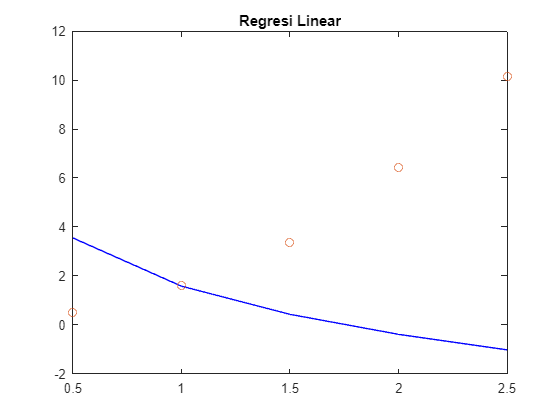


ln_f = zeros(1, 5); % Inisialisasi array untuk menyimpan nilai ln(f(x))

for i = 1:5
    ln_f(i) = log(C(2)) + C(1) * log(x(i)); % Menggunakan rumus ln(f(x)) = ln(a) + b*ln(x)
end

plot(x, ln_f, 'b', x, y, 'o');
title('Regresi Linear');